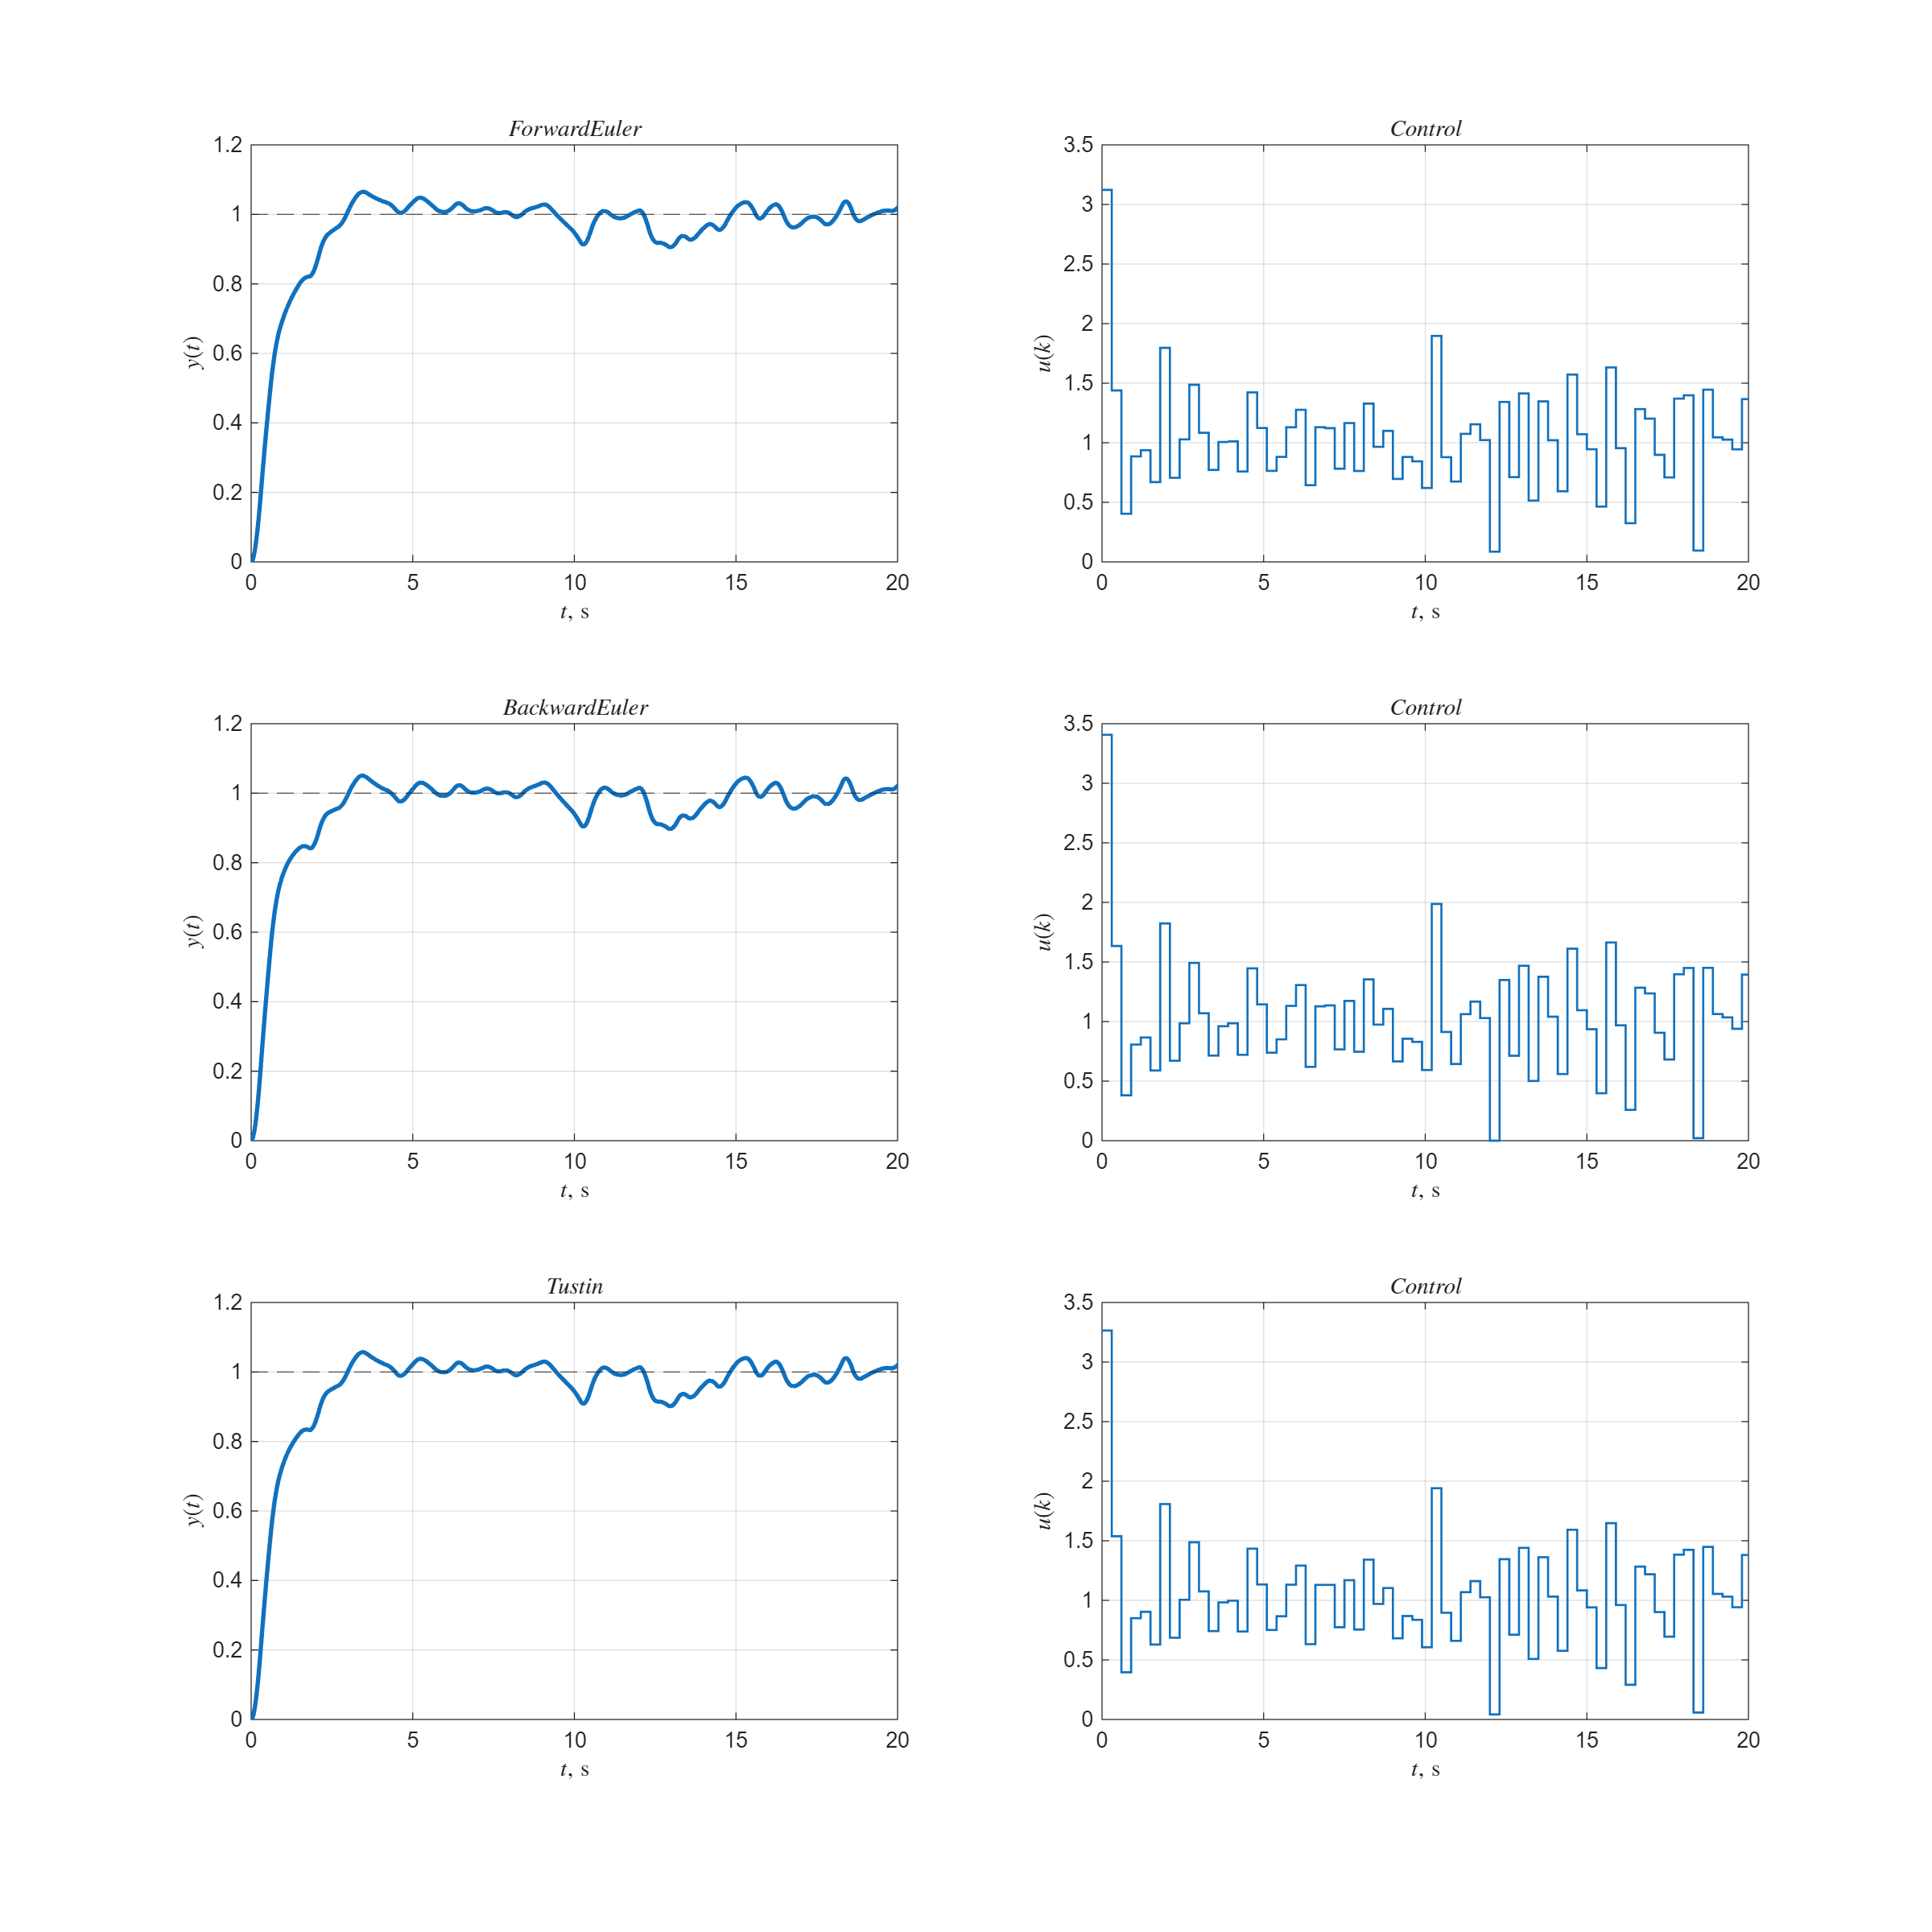

folder = "C:\Users\Nickolay\Desktop\ITMO-courses\7_term\Discrete_control_systems\lab4\tex\images\";

T1 = 0.6;
T2 = 0.9;

kp = T1 + T2;
ki = 1;
kd = T1*T2;

names = {"forward", "backward", "tustin"};
labels = {"Forward Euler", "Backward Euler", "Tustin"};

q0s = [1 1 1];
noiseVar = 0.01;

T = 0.3;
T2p = T2;

c = [kp+kd/T -kp+ki*T-2*kd/T kd/T;
     kp+ki*T+kd/T -kp-2*kd/T kd/T;
     kp+ki*T/2+kd/T -kp+ki*T/2-2*kd/T kd/T];

num1 = q0s(1)*c(1,:);
num2 = q0s(2)*c(2,:);
num3 = q0s(3)*c(3,:);

simtime = 25;
out1 = sim("lab4_pid.slx", simtime);

f = figure;
f.Position = [100 100 1200 1200];

for i = 1:3
    y = out1.get("y_"+names{i});
    u = out1.get("u_"+names{i});

    subplot(3,2,2*i-1);
    plot(y.Time,y.Data,LineWidth=2);
    yline(1,LineStyle="--");
    grid on;
    xlim([0 20]);
    title("$"+labels{i}+"$",Interpreter="latex");
    xlabel("$t,\;\mathrm{s}$",Interpreter="latex");
    ylabel("$y(t)$",Interpreter="latex");

    subplot(3,2,2*i);
    stairs(u.Time,u.Data,LineWidth=1);
    grid on;
    xlim([0 20]);
    title("$Control$",Interpreter="latex");
    xlabel("$t,\;\mathrm{s}$",Interpreter="latex");
    ylabel("$u(k)$",Interpreter="latex");
end

exportgraphics(f,fullfile(folder,"task2_pid_methods.png"),Resolution=600);

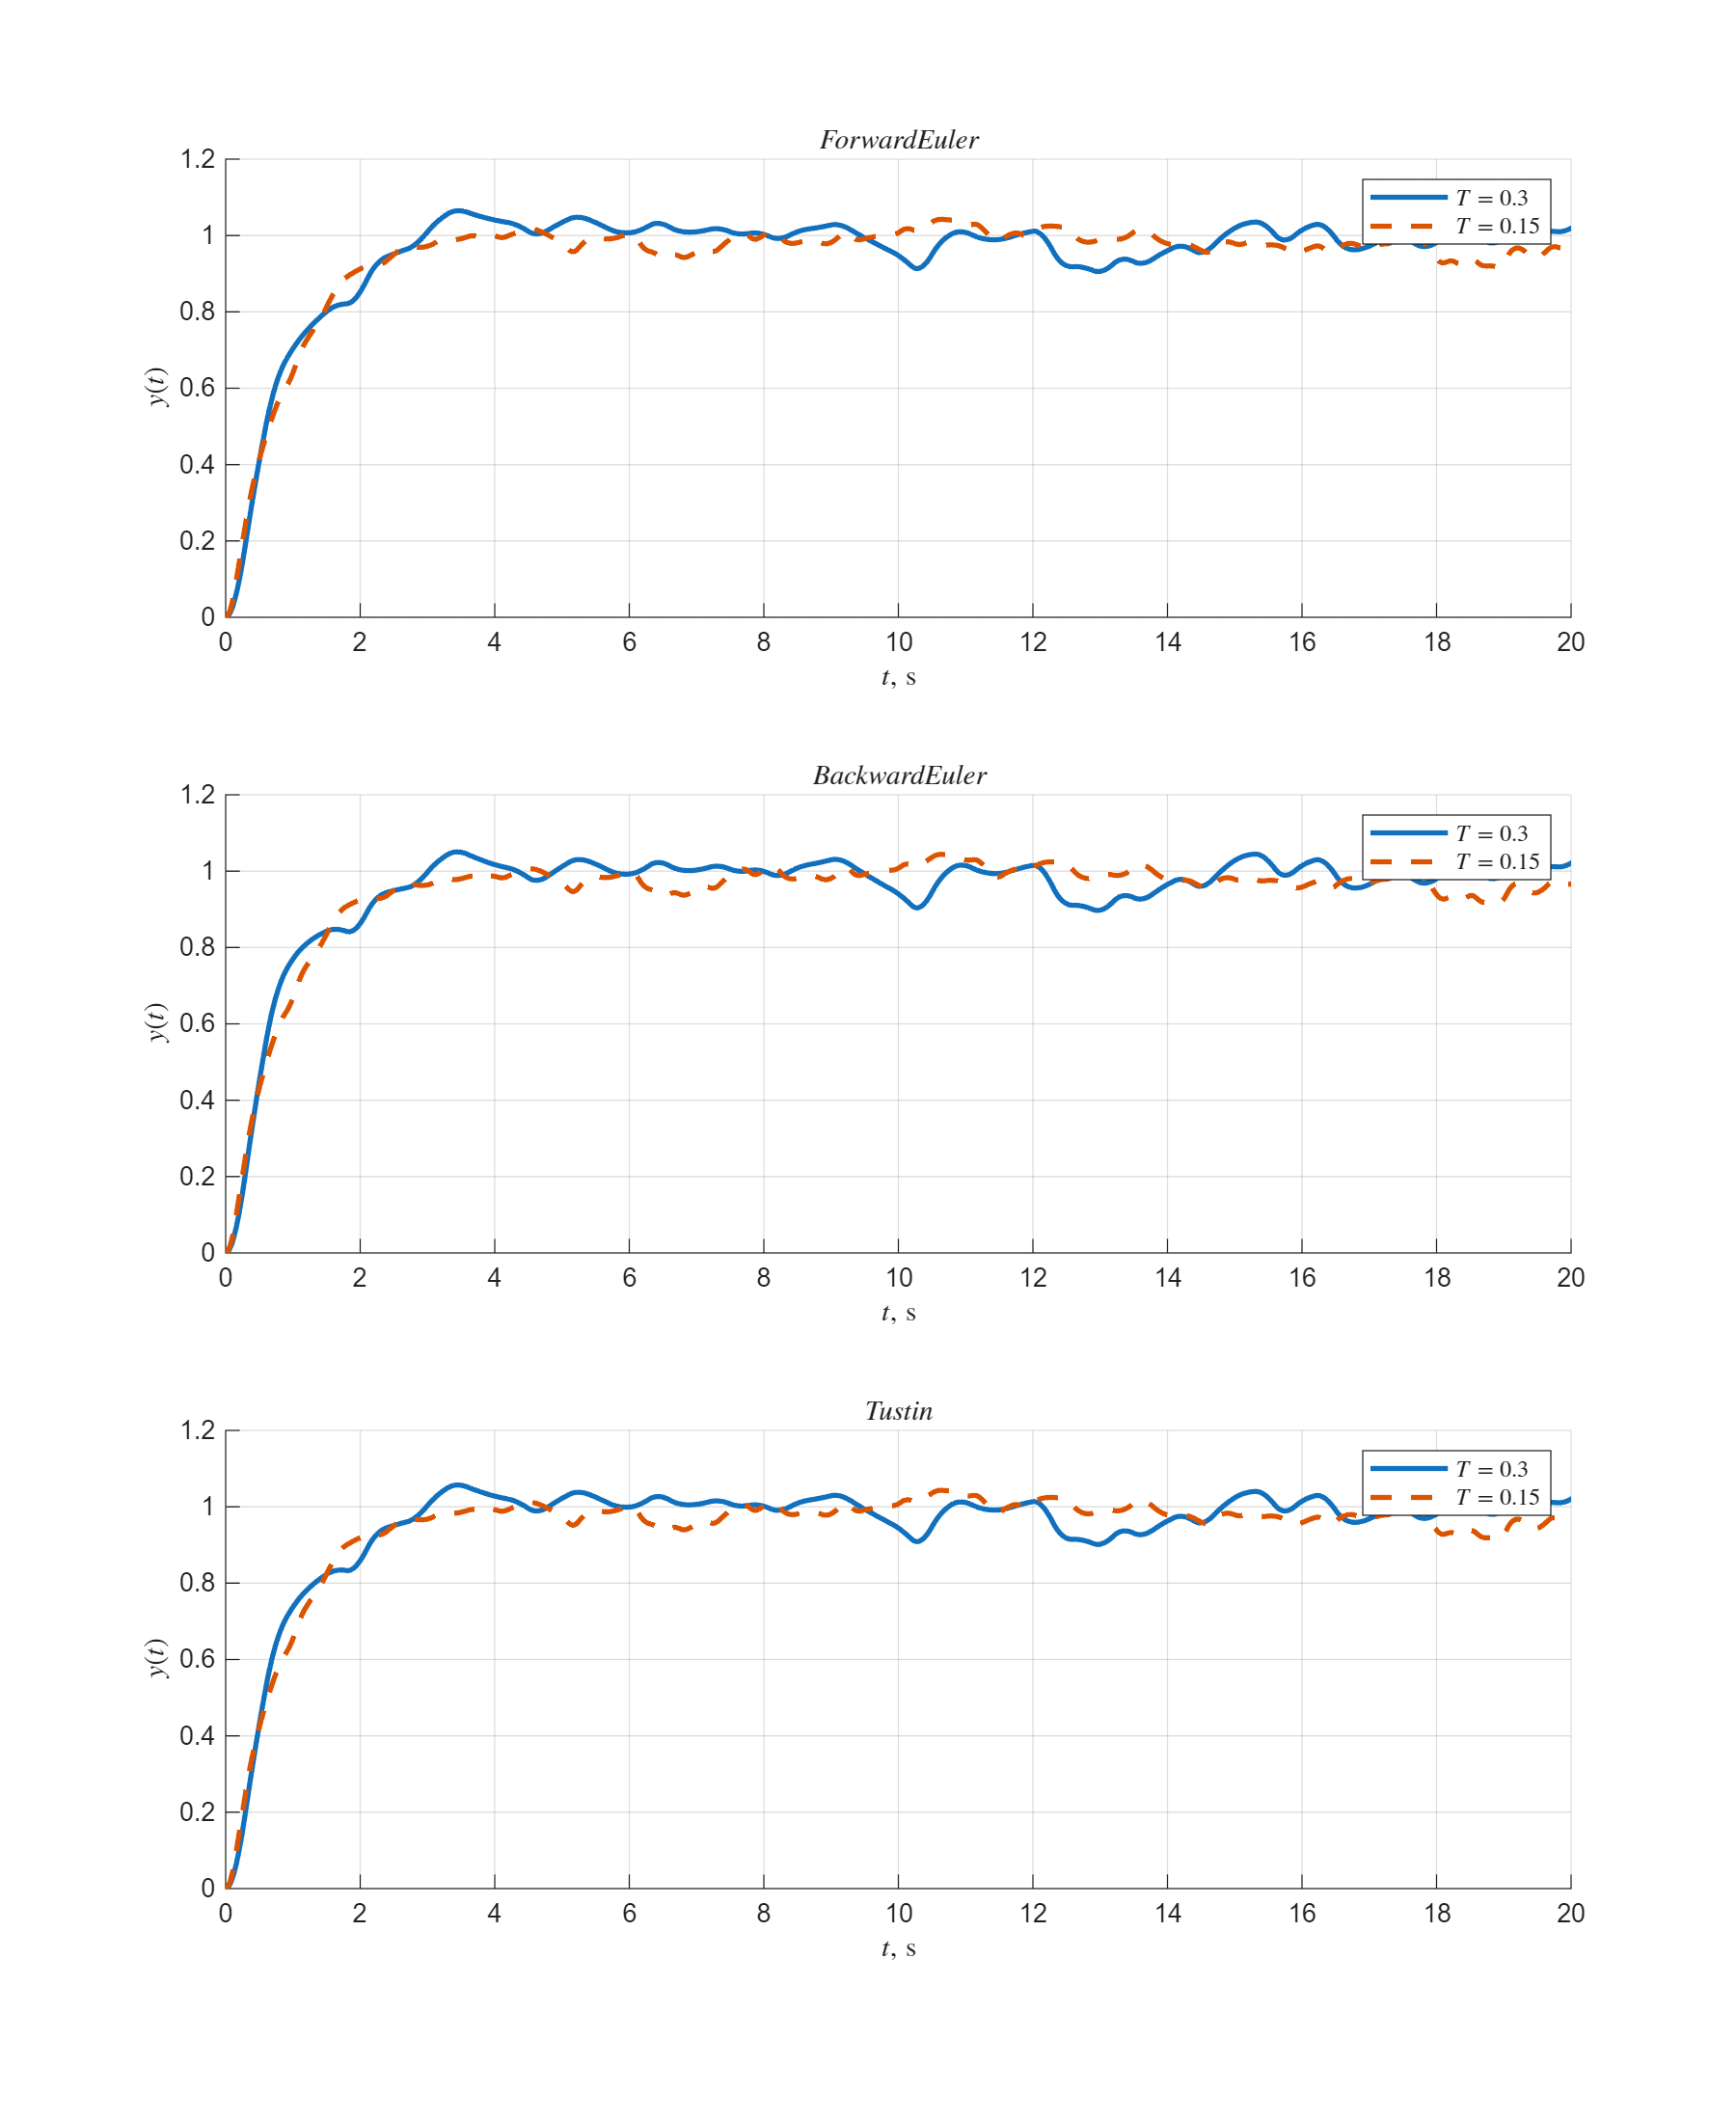



T = 0.15;

c = [kp+kd/T -kp+ki*T-2*kd/T kd/T;
     kp+ki*T+kd/T -kp-2*kd/T kd/T;
     kp+ki*T/2+kd/T -kp+ki*T/2-2*kd/T kd/T];

num1 = q0s(1)*c(1,:);
num2 = q0s(2)*c(2,:);
num3 = q0s(3)*c(3,:);

out2 = sim("lab4_pid.slx",simtime);

f = figure;
f.Position = [100 100 900 1100];

for i = 1:3
    y1 = out1.get("y_"+names{i});
    y2 = out2.get("y_"+names{i});

    subplot(3,1,i);
    hold on;
    plot(y1.Time,y1.Data,LineWidth=2);
    plot(y2.Time,y2.Data,LineStyle="--",LineWidth=2);
    hold off;

    legend({"$T=0.3$", "$T=0.15$"},Interpreter="latex");
    grid on;
    xlim([0 20]);
    title("$"+labels{i}+"$",Interpreter="latex");
    xlabel("$t,\;\mathrm{s}$",Interpreter="latex");
    ylabel("$y(t)$",Interpreter="latex");
end

exportgraphics(f,fullfile(folder,"task3_sample_period.png"),Resolution=600);

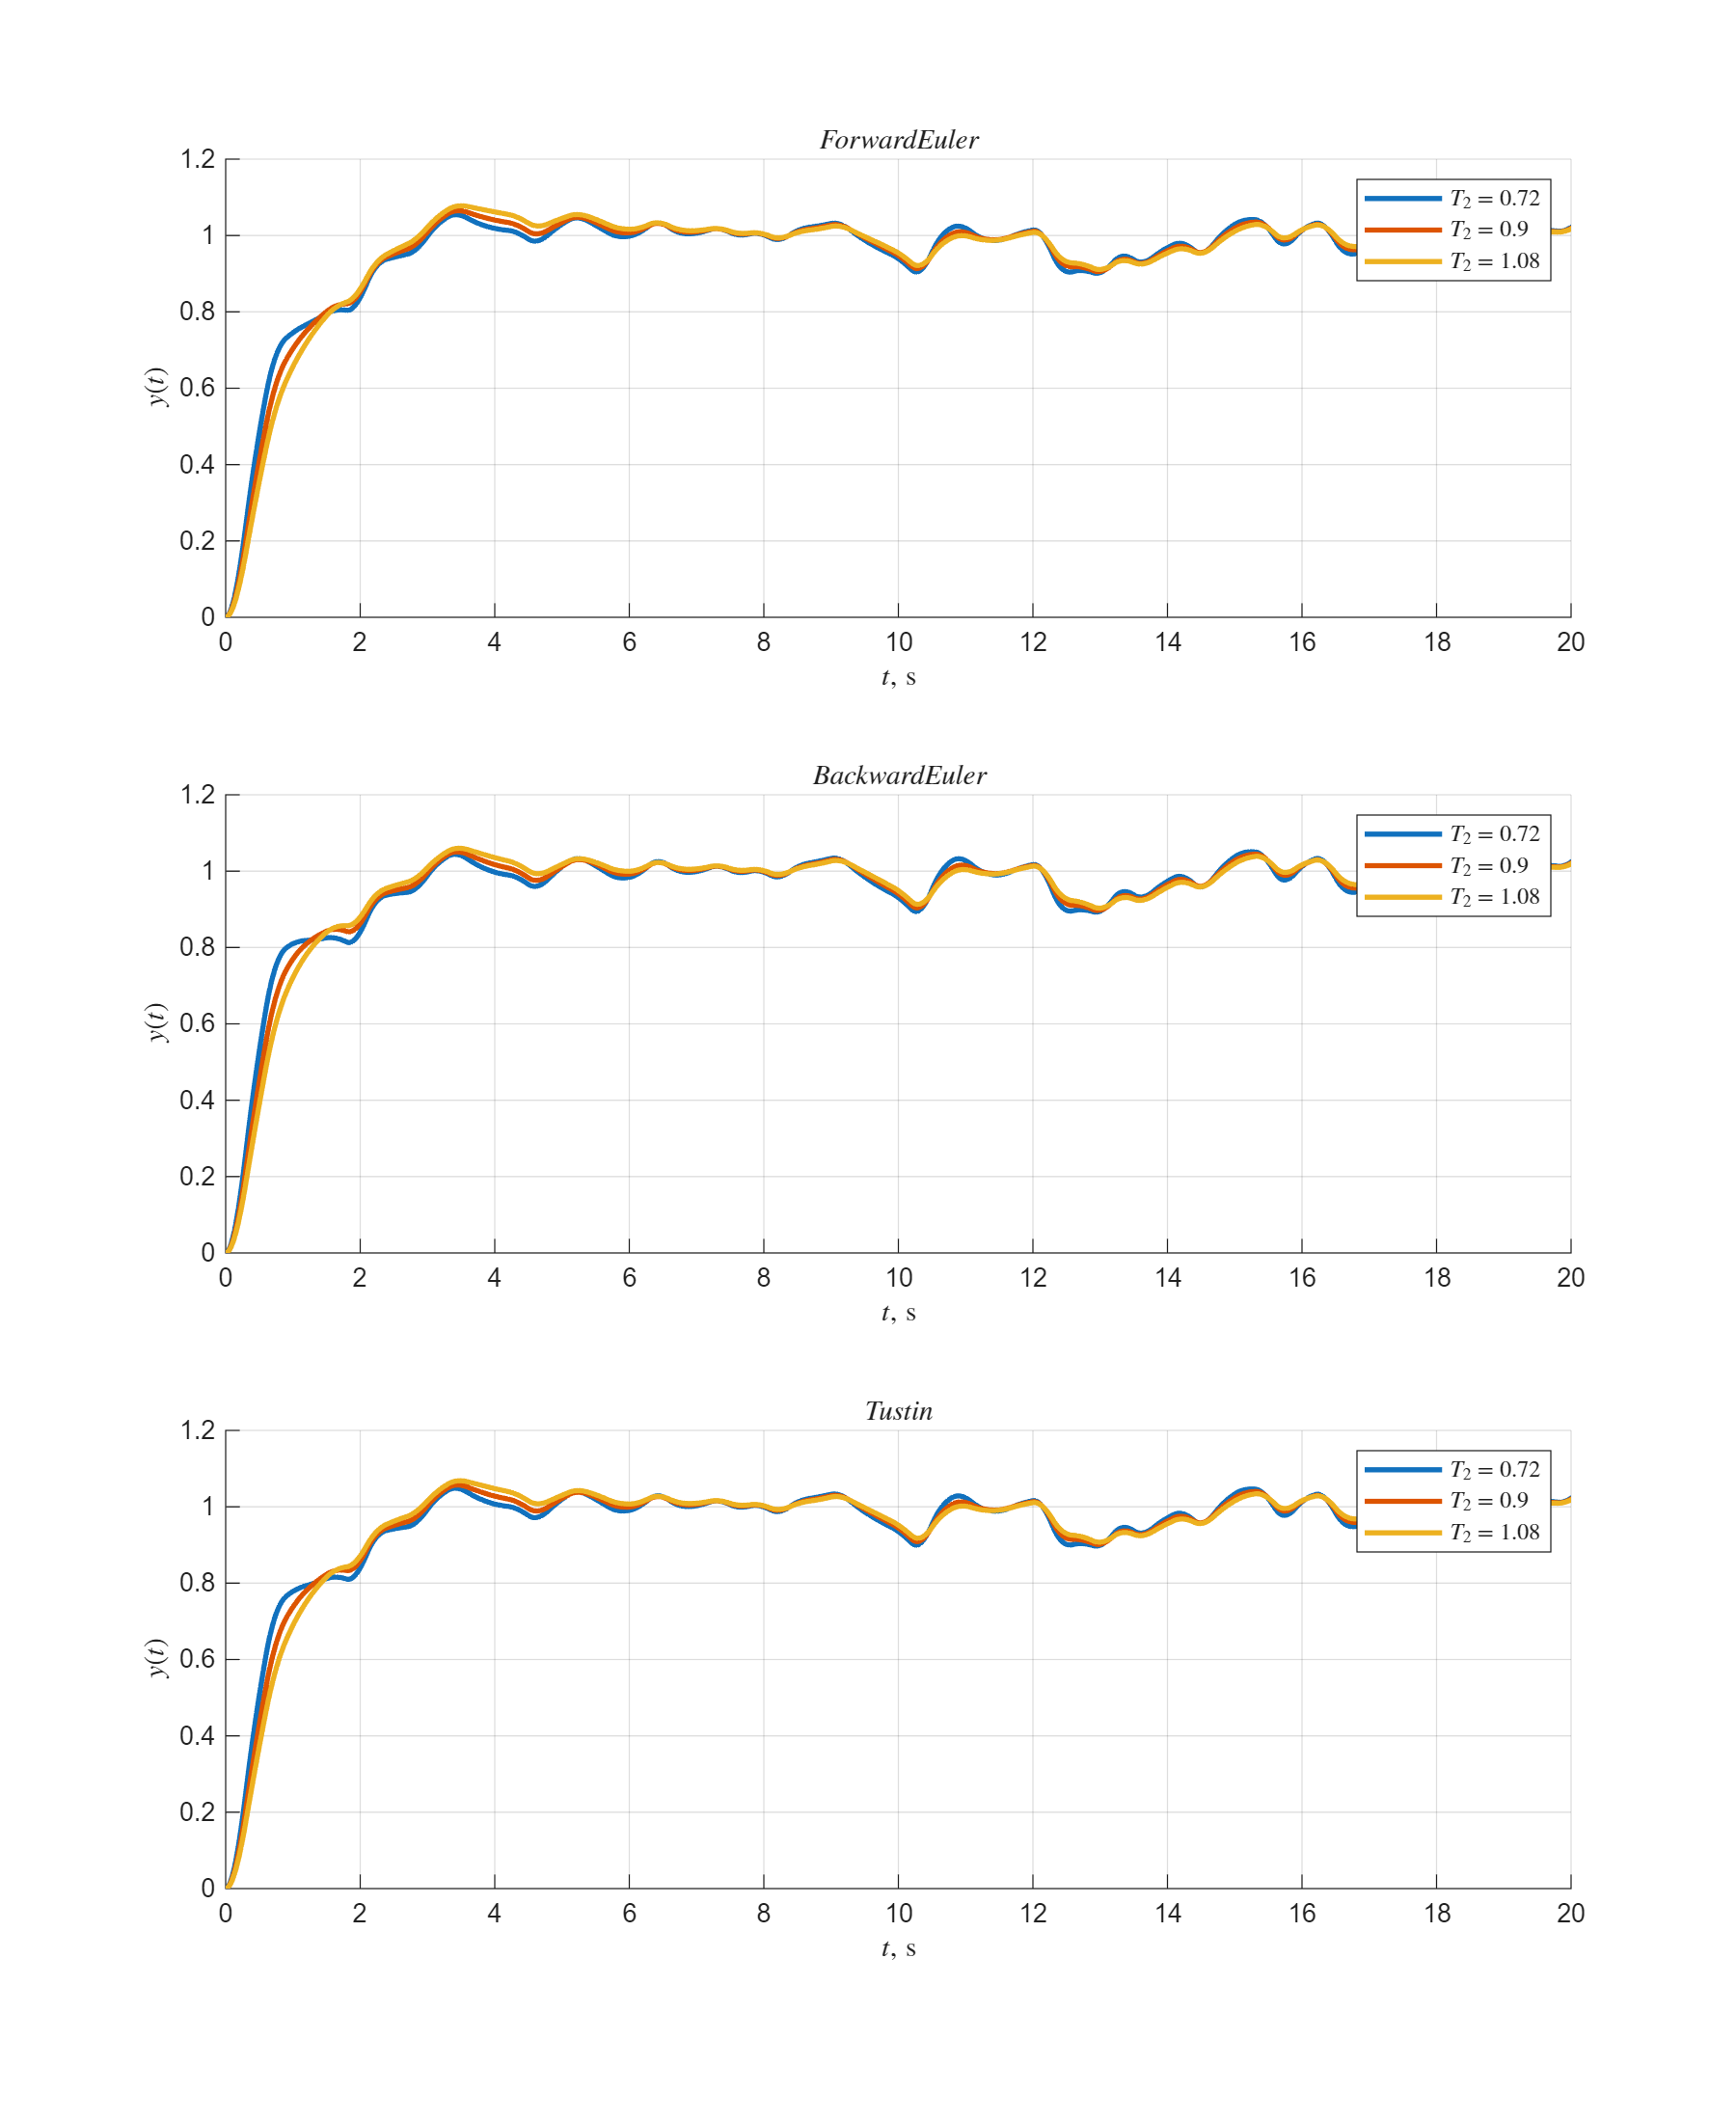



T = 0.3;

c = [kp+kd/T -kp+ki*T-2*kd/T kd/T;
     kp+ki*T+kd/T -kp-2*kd/T kd/T;
     kp+ki*T/2+kd/T -kp+ki*T/2-2*kd/T kd/T];

num1 = q0s(1)*c(1,:);
num2 = q0s(2)*c(2,:);
num3 = q0s(3)*c(3,:);

T2values = [0.72 0.9 1.08];

for j = 1:3
    T2p = T2values(j);
    outs{j} = sim("lab4_pid.slx",simtime);
end

f = figure;
f.Position = [100 100 900 1100];

for i = 1:3
    subplot(3,1,i);
    hold on;

    for j = 1:3
        y = outs{j}.get("y_"+names{i});
        plot(y.Time,y.Data,LineWidth=2);
    end

    hold off;

    legend({"$T_2=0.72$", "$T_2=0.9$", "$T_2=1.08$"}, ...
        Interpreter="latex");
    grid on;
    xlim([0 20]);
    title("$"+labels{i}+"$",Interpreter="latex");
    xlabel("$t,\;\mathrm{s}$",Interpreter="latex");
    ylabel("$y(t)$",Interpreter="latex");
end

exportgraphics(f,fullfile(folder,"task4_pole_compensation.png"),Resolution=600);

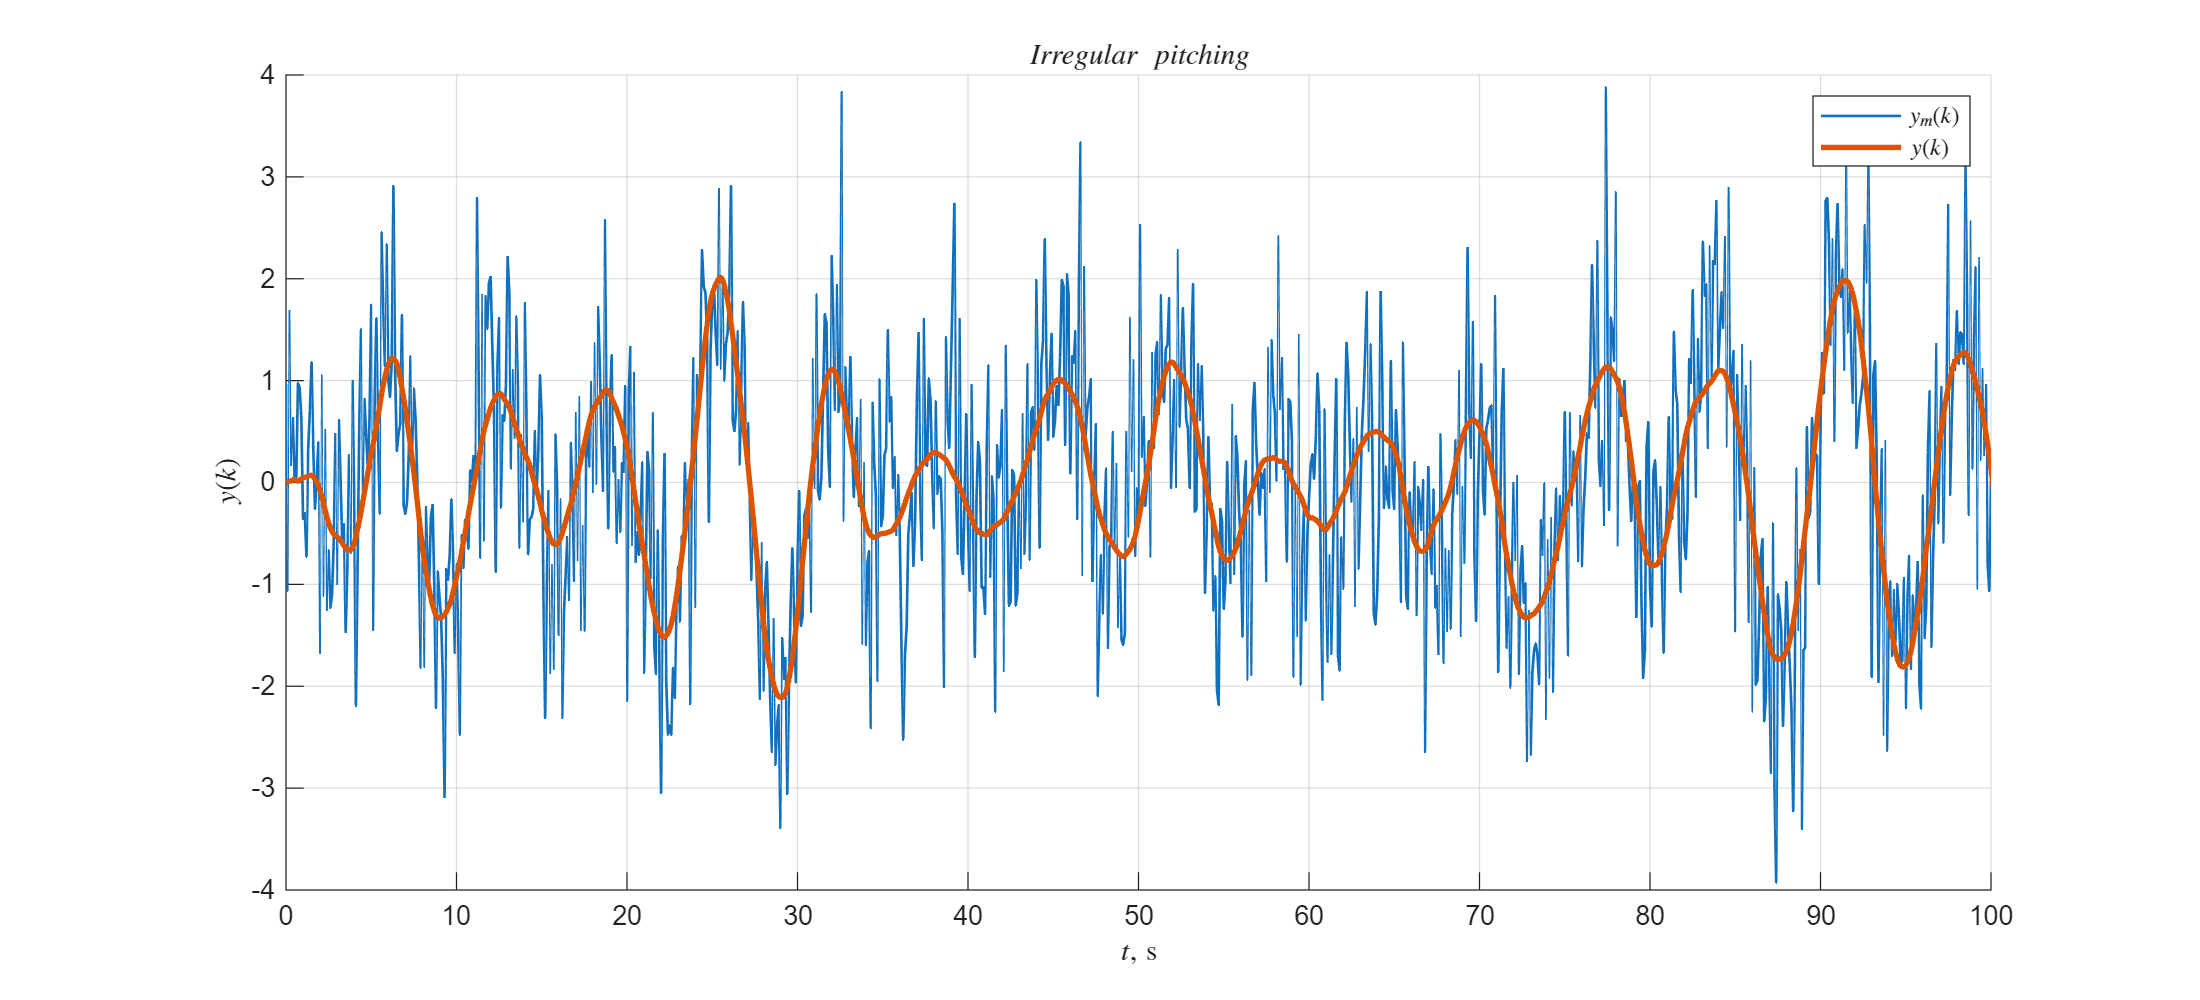



w0 = 0.9;
alpha = 0.05;
G0 = 2;
Q = 1.5;
R = 0.8;
h = 0.1;

Ak = [0 1; -w0^2 -2*alpha];
Bk = [0; w0^2];
Ck = [1 0];

sys = c2d(ss(Ak,Bk,Ck,0),h,"zoh");
Ah = sys.A;
Bh = sys.B;

Qx = Bh*Q*Bh';
P = dare(Ah',Ck',Qx,R);
Kk = P*Ck'/(Ck*P*Ck'+R);

Aobs = Ah*(eye(2)-Kk*Ck);
Bobs = Ah*Kk;
Cobs = Ck*(eye(2)-Kk*Ck);
Dobs = Ck*Kk;

simtime = 200;
out = sim("lab4_pitch.slx",simtime);

y = out.y_true.Data;
ym = out.y_meas.Data;
yh = out.y_est.Data;
t = out.y_true.Time;

f = figure;
f.Position = [100 100 1100 500];

hold on;
plot(t,ym,LineWidth=1);
plot(t,y,LineWidth=2);
hold off;

legend({"$y_m(k)$", "$y(k)$"},Interpreter="latex");
grid on;
xlim([0 100]);
title("$Irregular\ pitching$",Interpreter="latex");
xlabel("$t,\;\mathrm{s}$",Interpreter="latex");
ylabel("$y(k)$",Interpreter="latex");

exportgraphics(f,fullfile(folder,"task5_pitching.png"),Resolution=600);

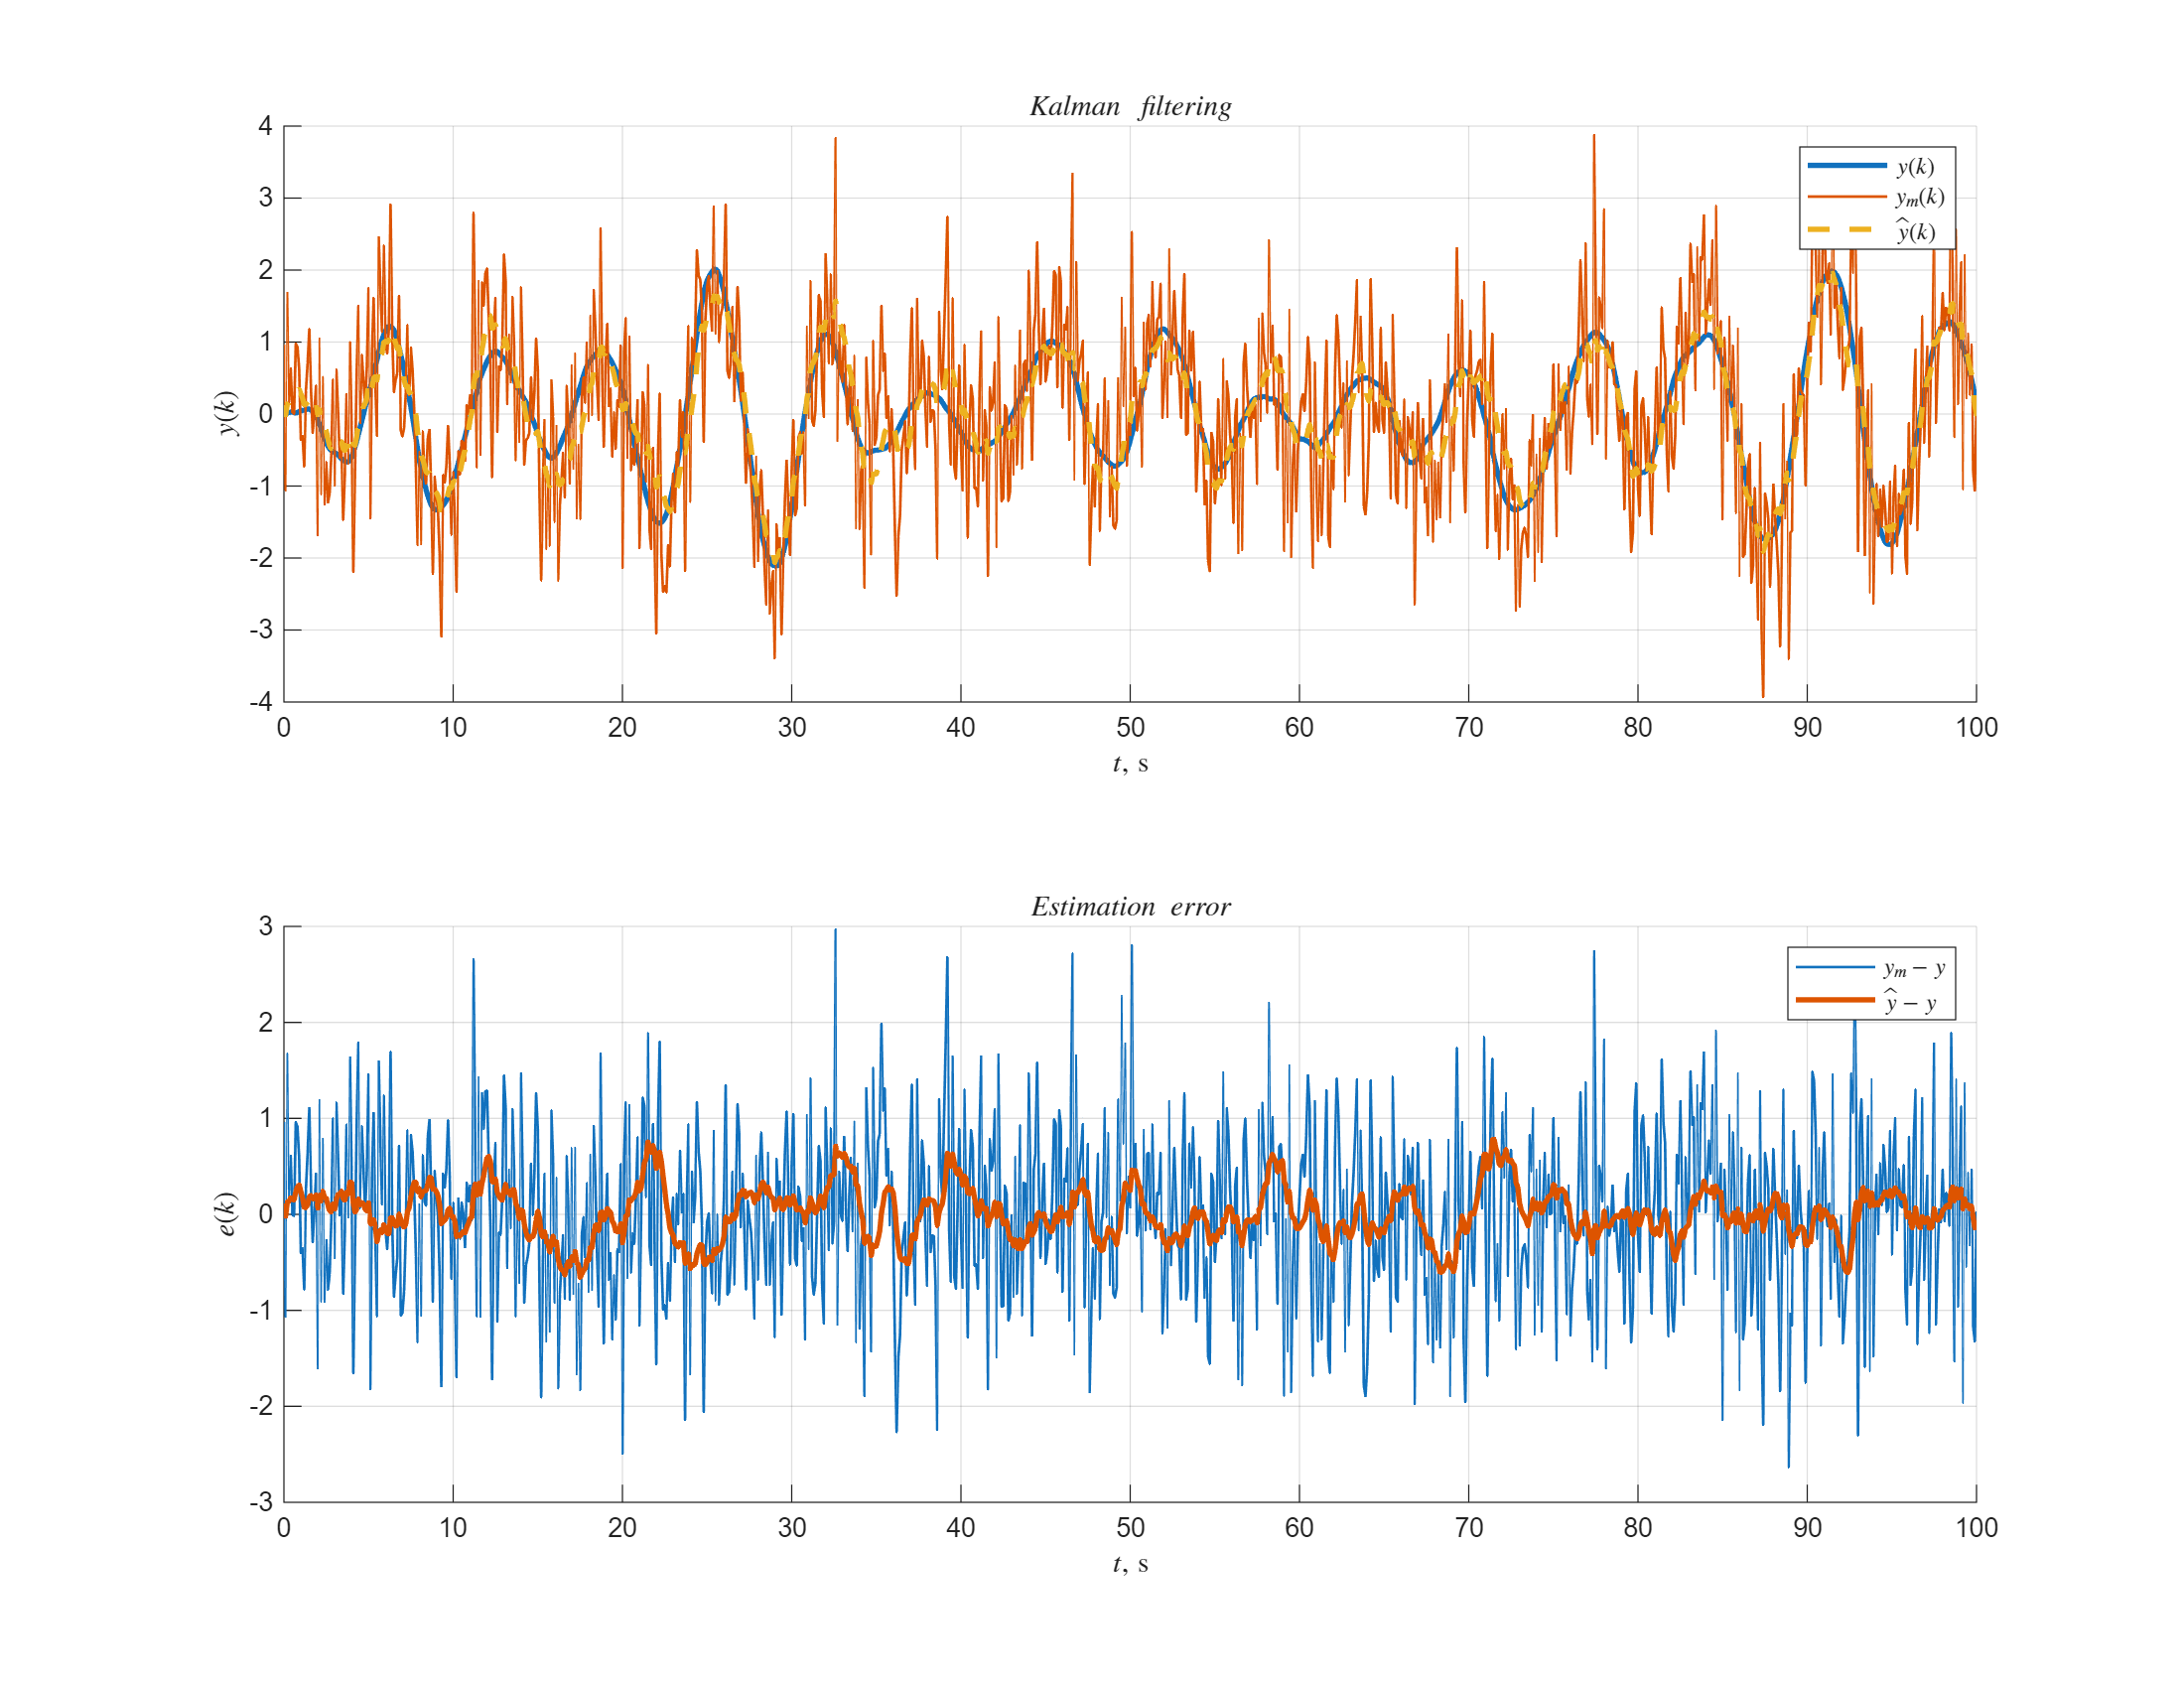



f = figure;
f.Position = [100 100 1100 850];

subplot(2,1,1);
hold on;
plot(t,y,LineWidth=2);
plot(t,ym,LineWidth=1);
plot(t,yh,LineStyle="--",LineWidth=2);
hold off;

legend({"$y(k)$","$y_m(k)$","$\hat y(k)$"},Interpreter="latex");
grid on;
xlim([0 100]);
title("$Kalman\ filtering$",Interpreter="latex");
xlabel("$t,\;\mathrm{s}$",Interpreter="latex");
ylabel("$y(k)$",Interpreter="latex");

subplot(2,1,2);
hold on;
plot(t,ym-y,LineWidth=1);
plot(t,yh-y,LineWidth=2);
hold off;

legend({"$y_m-y$", "$\hat y-y$"},Interpreter="latex");
grid on;
xlim([0 100]);
title("$Estimation\ error$",Interpreter="latex");
xlabel("$t,\;\mathrm{s}$",Interpreter="latex");
ylabel("$e(k)$",Interpreter="latex");

exportgraphics(f,fullfile(folder,"task7_pitching_kalman.png"),Resolution=600);

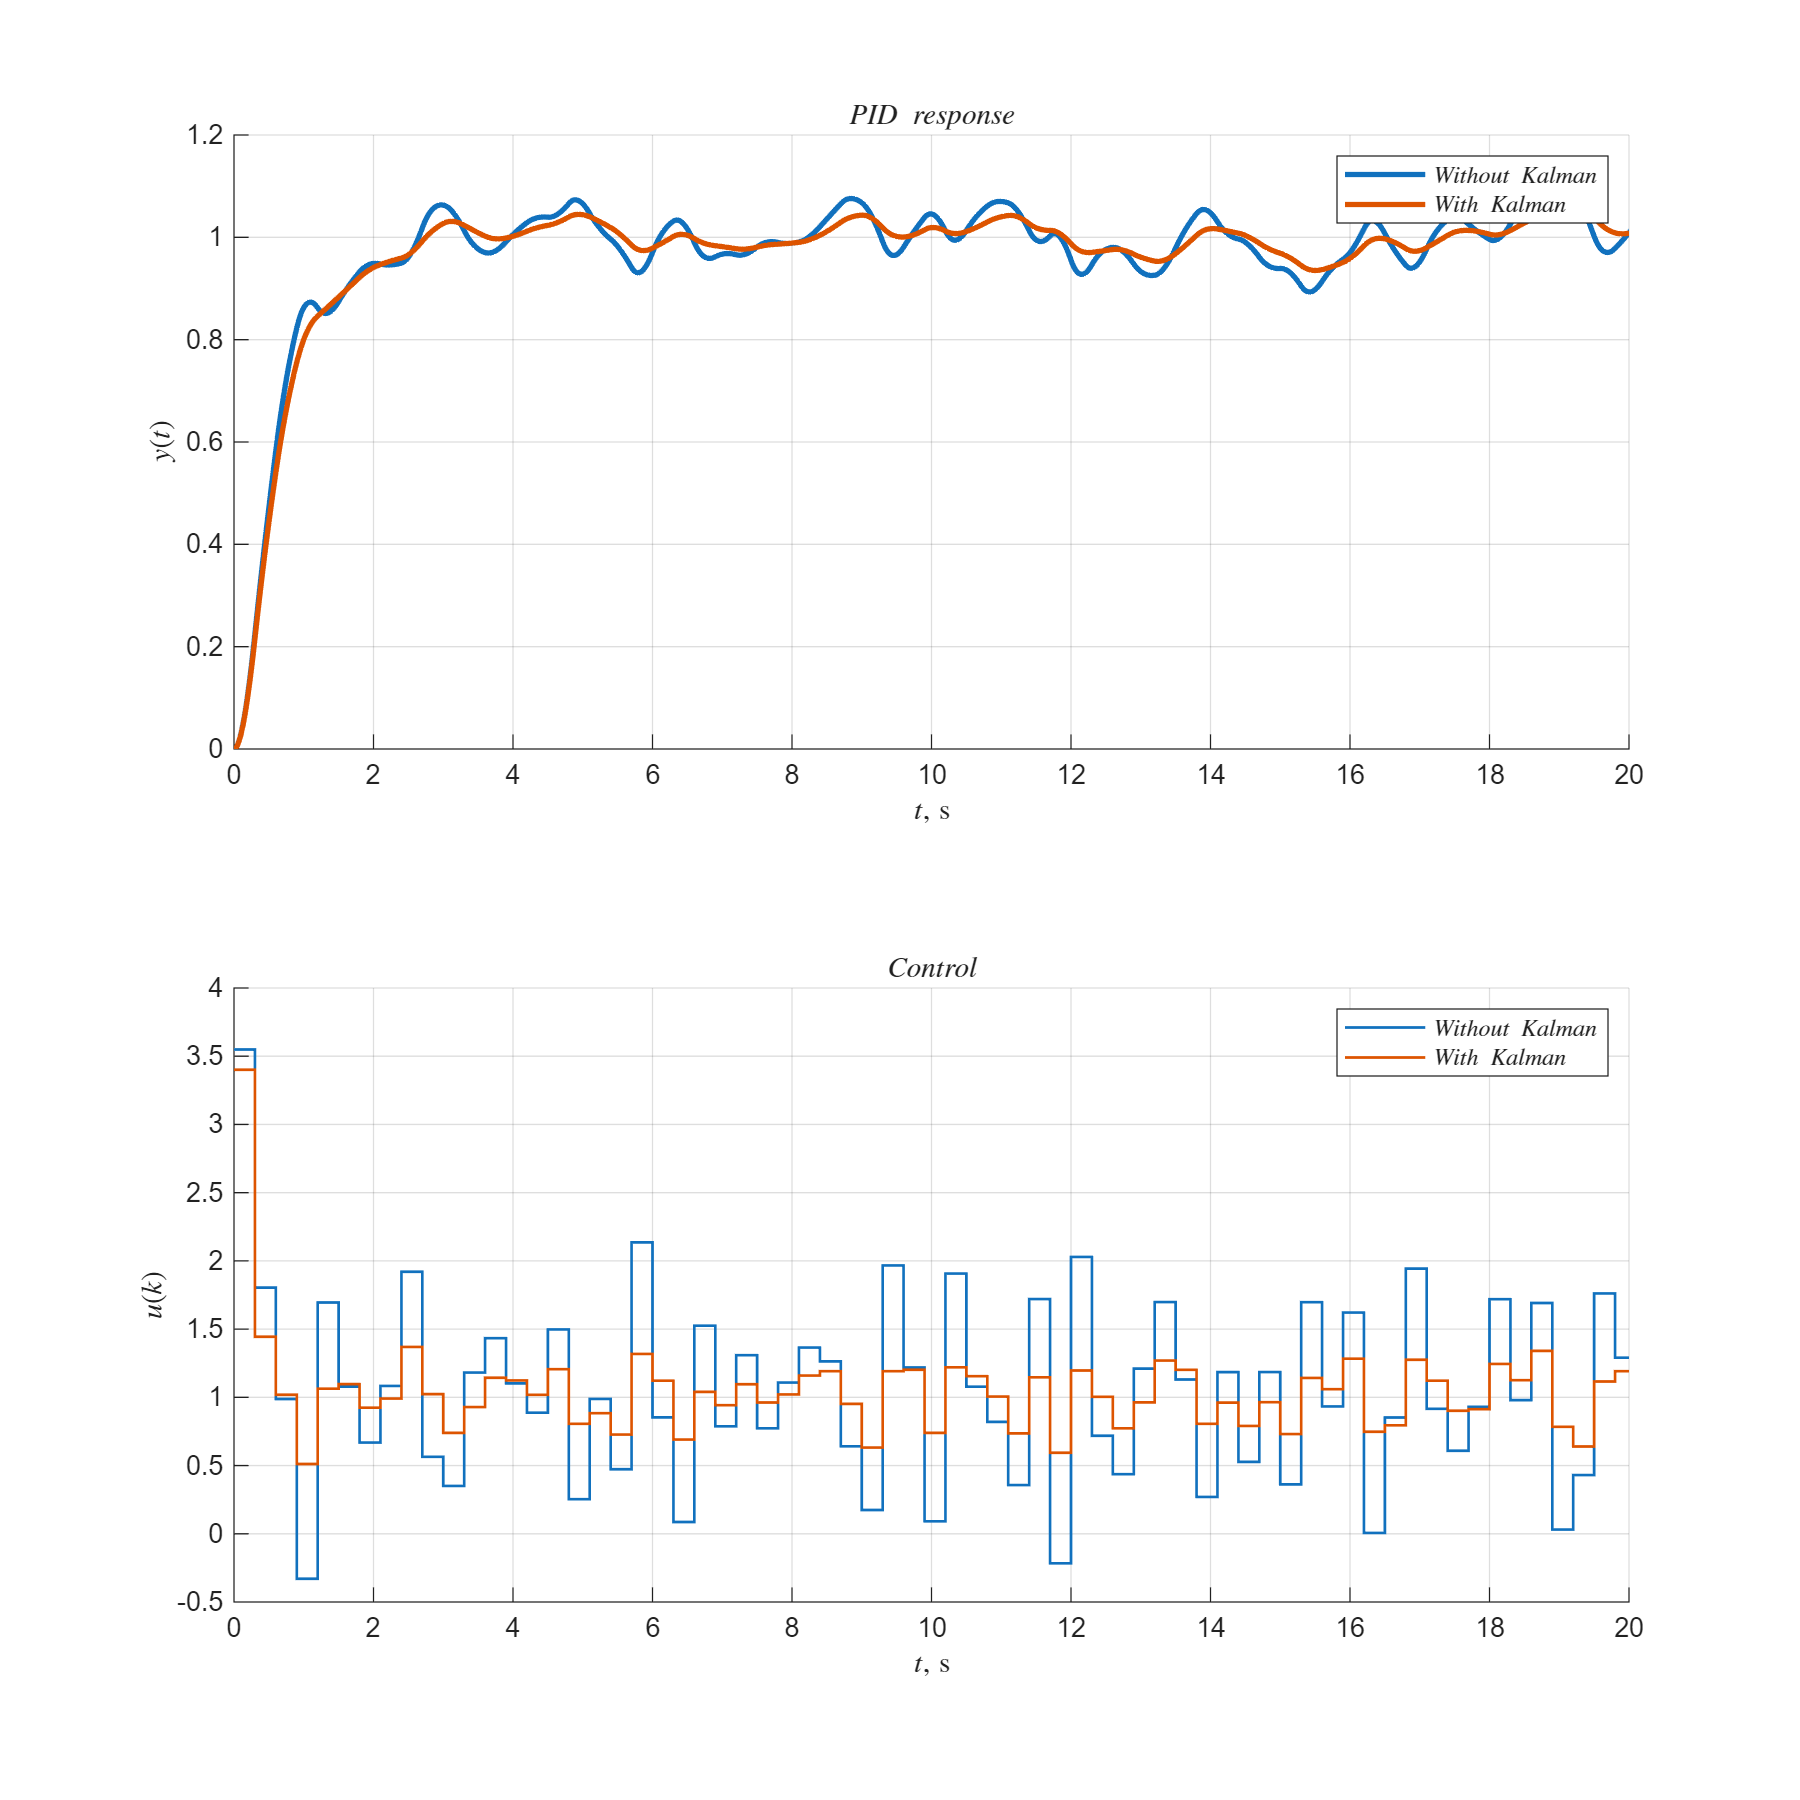


rmse_measurement = sqrt(mean((ym-y).^2));
rmse_kalman = sqrt(mean((yh-y).^2));


T = 0.3;
T2p = T2;
Rpid = 0.03;
Qpid = 0.01*eye(2);

A0 = [0 1; -1/(T1*T2) -(T1+T2)/(T1*T2)];
B0 = [0; 1/(T1*T2)];
C0 = [1 0];

sys = c2d(ss(A0,B0,C0,0),T,"zoh");
Ad = sys.A;
Bd = sys.B;

Ppid = dare(Ad',C0',Qpid,Rpid);
Kpid = Ppid*C0'/(C0*Ppid*C0'+Rpid);

Akal = Ad*(eye(2)-Kpid*C0);
Bkal = [Ad*Kpid Bd];
Ckal = C0*(eye(2)-Kpid*C0);
Dkal = [C0*Kpid 0];

c = [kp+kd/T -kp+ki*T-2*kd/T kd/T;
     kp+ki*T+kd/T -kp-2*kd/T kd/T;
     kp+ki*T/2+kd/T -kp+ki*T/2-2*kd/T kd/T];

num1 = q0s(1)*c(1,:);

simtime = 25;
out = sim("lab4_pid_kalman.slx",simtime);
y1 = out.y_raw.Data;
t1 = out.y_raw.Time;
u1 = out.u_raw.Data;
tu1 = out.u_raw.Time;

y2 = out.y_kal.Data;
t2 = out.y_kal.Time;
u2 = out.u_kal.Data;
tu2 = out.u_kal.Time;

f = figure;
f.Position = [100 100 900 900];

subplot(2,1,1);
hold on;
plot(t1,y1,LineWidth=2);
plot(t2,y2,LineWidth=2);
hold off;

legend({"$Without\ Kalman$", "$With\ Kalman$"},Interpreter="latex");
grid on;
xlim([0 20]);
title("$PID\ response$",Interpreter="latex");
xlabel("$t,\;\mathrm{s}$",Interpreter="latex");
ylabel("$y(t)$",Interpreter="latex");

subplot(2,1,2);
hold on;
stairs(tu1,u1,LineWidth=1);
stairs(tu2,u2,LineWidth=1);
hold off;

legend({"$Without\ Kalman$", "$With\ Kalman$"},Interpreter="latex");
grid on;
xlim([0 20]);
title("$Control$",Interpreter="latex");
xlabel("$t,\;\mathrm{s}$",Interpreter="latex");
ylabel("$u(k)$",Interpreter="latex");

exportgraphics(f,fullfile(folder,"task8_pid_kalman.png"),Resolution=600);